% High pass filter in frequency domain
K=500;
k=-K:K;
N=31;
n=0:2*50;
w=k*pi/K

w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


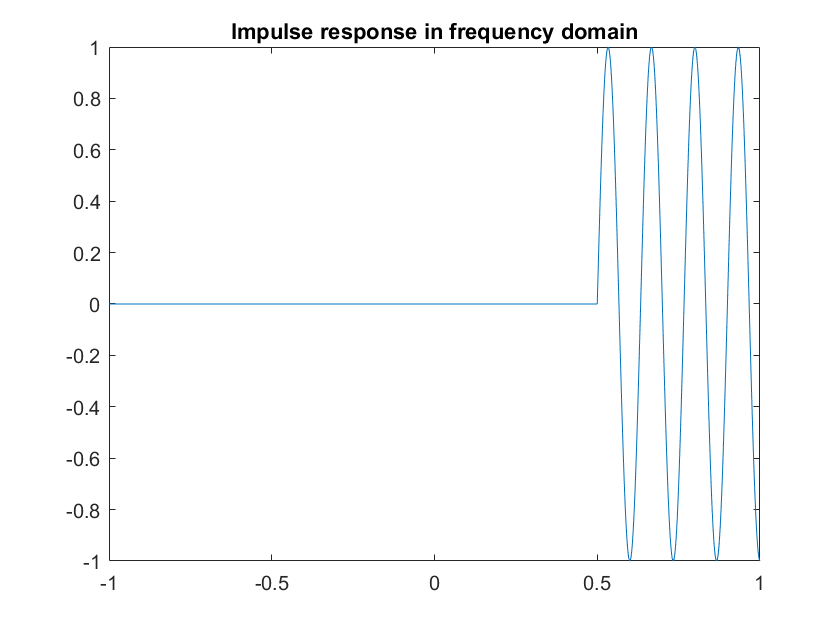

Hd=w;
% prb 3.8.1
a=15;
wc=0.5*pi;
for i=1:length(w)
    if w(i)>wc
        Hd(i)=exp(-1j*a*w(i));
    else
        Hd(i)=0;
    end
end
figure("Name",'DTFT')
plot(w/pi,real(Hd))
title('Impulse response in frequency domain')

[hd,n]=idtft(Hd,n,w)

hd =    0.0101 - 0.0111i   0.0010 + 0.0227i  -0.0127 - 0.0117i  -0.0000 - 0.0000i   0.0140 - 0.0150i   0.0010 + 0.0318i  -0.0182 - 0.0172i  -0.0000 + 0.0000i   0.0222 - 0.0232i   0.0010 + 0.0530i  -0.0323 - 0.0313i  -0.0000 - 0.0000i   0.0526 - 0.0536i   0.0010 + 0.1592i  -0.1597 - 0.1587i   0.2500 + 0.0000i  -0.1597 + 0.1587i   0.0010 - 0.1592i   0.0526 + 0.0536i  -0.0000 + 0.0000i  -0.0323 + 0.0313i   0.0010 - 0.0530i   0.0222 + 0.0232i  -0.0000 - 0.0000i  -0.0182 + 0.0172i   0.0010 - 0.0318i   0.0140 + 0.0150i  -0.0000 - 0.0000i  -0.0127 + 0.0117i   0.0010 - 0.0227i   0.0101 + 0.0111i   0.0000 + 0.0000i  -0.0099 + 0.0089i   0.0010 - 0.0177i   0.0079 + 0.0089i   0.0000 - 0.0000i  -0.0081 + 0.0071i   0.0010 - 0.0144i   0.0064 + 0.0074i   0.0000 + 0.0000i  -0.0069 + 0.0059i   0.0010 - 0.0122i   0.0054 + 0.0064i   0.0000 - 0.0000i  -0.0060 + 0.0050i   0.0010 - 0.0106i   0.0046 + 0.0056i   0.0000 + 0.0000i  -0.0053 + 0.0043i   0.0010 - 0.0093i


n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


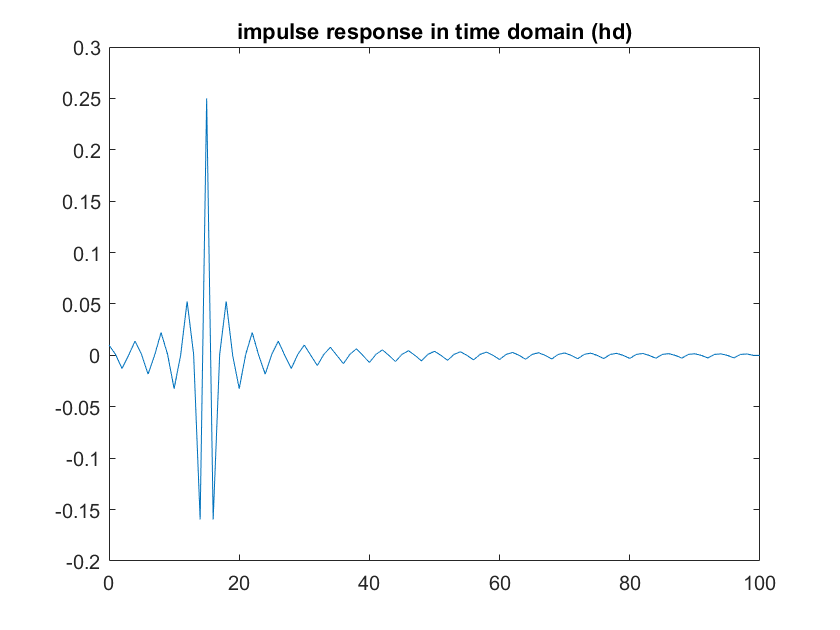

figure("Name",'IDTFT')
plot(n,real(hd))
title('impulse response in time domain (hd)')

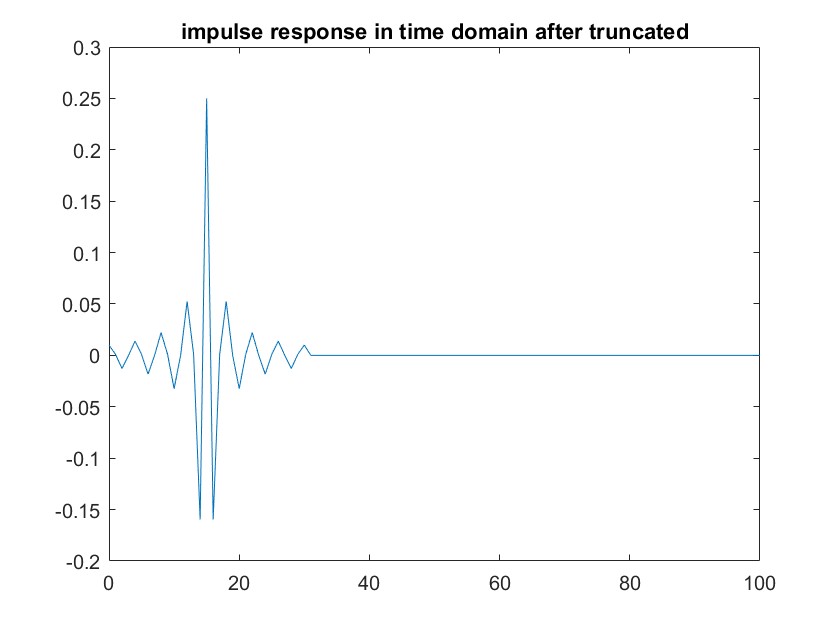

% end prb 3.8.1
% start prb 3.8.2
h=hd;
for i=1:length(n)
    if n(i)>N
        h(i)=0;
    end
end
figure("Name",'IDTFT')
plot(n,real(h))
title('impulse response in time domain after truncated')

% end prb 3.8.2
% start prb 3.8.3
[H,w]=dtft(h,n,w)

H =   -0.5061 + 0.0000i  -0.4720 + 0.0446i  -0.4344 + 0.0829i  -0.3944 + 0.1146i  -0.3528 + 0.1397i  -0.3107 + 0.1583i  -0.2689 + 0.1707i  -0.2283 + 0.1771i  -0.1896 + 0.1781i  -0.1535 + 0.1742i  -0.1206 + 0.1659i  -0.0911 + 0.1541i  -0.0656 + 0.1394i  -0.0441 + 0.1224i  -0.0267 + 0.1040i  -0.0134 + 0.0848i  -0.0041 + 0.0655i   0.0015 + 0.0466i   0.0036 + 0.0288i   0.0028 + 0.0124i  -0.0007 - 0.0021i  -0.0063 - 0.0145i  -0.0135 - 0.0246i  -0.0219 - 0.0322i  -0.0309 - 0.0374i  -0.0401 - 0.0401i  -0.0491 - 0.0406i  -0.0574 - 0.0390i  -0.0648 - 0.0356i  -0.0710 - 0.0307i  -0.0757 - 0.0246i  -0.0789 - 0.0176i  -0.0804 - 0.0102i  -0.0803 - 0.0025i  -0.0787 + 0.0049i  -0.0755 + 0.0120i  -0.0711 + 0.0183i  -0.0656 + 0.0236i  -0.0593 + 0.0279i  -0.0523 + 0.0309i  -0.0450 + 0.0327i  -0.0376 + 0.0331i  -0.0304 + 0.0323i  -0.0235 + 0.0303i  -0.0173 + 0.0272i  -0.0119 + 0.0233i  -0.0073 + 0.0185i  -0.0039 + 0.0133i  -0.0015 + 0.0077i  -0.0002 + 0.0020i


w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


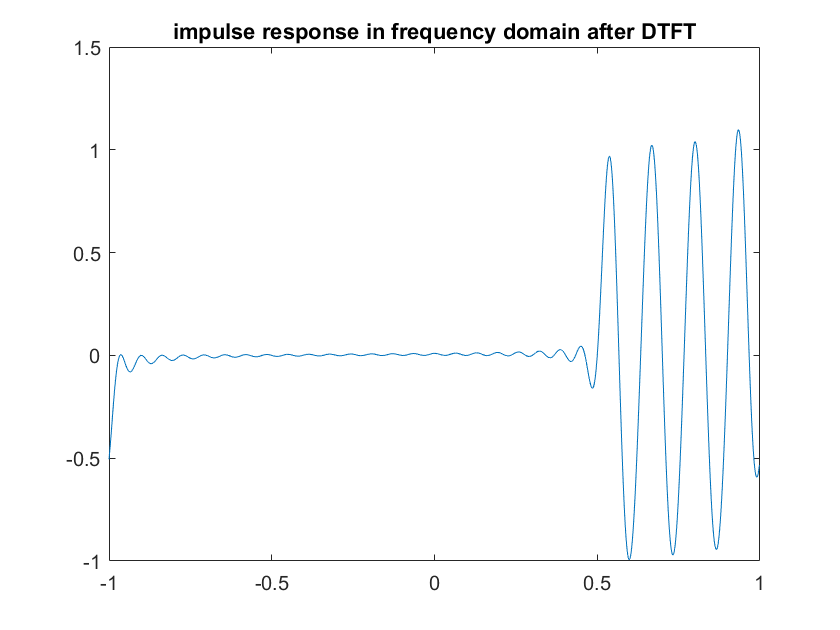

figure("Name",'DTFT of signal h')
plot(w/pi,real(H))
title('impulse response in frequency domain after DTFT')

%comment about the observation of H and Hd
% here i see some noise after cutoff frequency in H signal and maximu error
% is 0.4781
error=(max(abs(real(Hd)-real(H)))),%/max(real(h))

error = 0.5061

% end prb 3.8.3
% h=movmean(h,5)
% figure("Name",' IDTFT after mm')
% plot(n,real(h))
% title('impulse response in time domain after mm')
% 
% h=spline(n*(1/1),h,n)
% figure("Name",'IDTFT after spline')
% plot(n,real(h))
% title('impulse response in time domain after spline')

